# **Computational Vision - Project 2 Report**

**Topic A3:   People and Vehicle Detection using Thermal Imagery**

Authors:

- David Marafuz Gaspar - 106541 - david.marafuz.gaspar@tecnico.ulisboa.pt

- Pedro Gaspar Monico - 106626 - pedro.monico@tecnico.ulisboa.pt

Supervisors:

- Prof. Alexandra Moutinho

- Eng. Alexandre Athayde

## 1. Introduction

With the rapid advancement of autonomous driving and Advanced Driver-Assistance Systems (ADAS), the ability to reliably detect pedestrians and vehicles in real-time has become a fundamental requirement for safe road navigation. Traditional RGB-based vision systems, while effective under standard conditions, are inherently limited by their dependence on visible light, making them prone to failure in challenging environments such as darkness, fog, heavy rain, or glare which are precisely the conditions where robust perception is most critical for the safety of both passengers and other road users.

Thermal imaging offers a compelling alternative, as it captures heat signatures emitted naturally by humans and vehicles rather than relying on reflected light. This makes thermal-based detection largely invariant to lighting conditions, providing a more consistent and reliable perception pipeline for safety-critical applications. Unlike RGB cameras, thermal sensors can preserve the distinct silhouettes of pedestrians and vehicles even in the most adverse scenarios. These properties make thermal sensors an increasingly attractive complement to visible-light cameras in modern ADAS systems.

This project aims to develop and optimize a deep learning-based object detection model using the FLIR ADAS dataset. The goal is to build a system capable of accurately detecting pedestrians and vehicles in real driving scenarios. This report details the following steps:

- **Dataset Analysis and Preparation:** Characterisation of the FLIR ADAS thermal dataset, identification and consolidation of relevant object classes into two semantically meaningful categories (Person and Vehicle), and the structuring of a representative data subset for training, validation, and testing;

- **Object Detection Pipeline:** Design, deployment, and iterative optimisation of an object detection system based on the YOLOv2 architecture with a SqueezeNet backbone, leveraging transfer learning and data-driven anchor box estimation as a performance benchmark, followed by targeted improvements through advanced data augmentation strategies, hyperparameter tuning, optimizer selection, and backbone comparison between SqueezeNet and GoogLeNet architectures;

- **Results and Discussion:** Rigorous assessment of both the baseline and optimised models using standard computer vision metrics, including Average Precision (AP) per class, mean Average Precision (mAP), and Precision-Recall curves;

- **Cross-Modality Evaluation:** Assessment of the champion model's generalisation capability by evaluating its performance on both thermal and RGB test sets, providing insight into the domain-specific limitations of the trained system.

It is important to note that the FLIR ADAS dataset is approximately 11 GB in size. Due to this large volume, it cannot be included directly with the project files. To run the live scripts and replicate the results, it is necessary to download the dataset from the official source before executing any data processing or training steps creating a /Data directory.

**Attention:** The FLIR ADAS dataset is approximately 11 GB in size and cannot be included directly with the project files. To run the live scripts and replicate the results, it is necessary to download the dataset from the official source and place it in a `/Data` directory before executing any data processing or training steps. Additionally, to reduce clutter in the report, auxiliary scripts including model training routines and other supporting functions have been organised into separate files and are only referenced in the code when invoked. These auxiliary functions follow the naming convention `aux_<function>.m`.

## 2. Dataset Analysis and Preparation

### 2.1 Dataset Overview

To provide an intuitive understanding of the thermal modality used throughout this project, Figure 1 presents a representative thermal image from the FLIR ADAS dataset [1] alongside a comparable RGB image captured under similar driving conditions. Note that the two images are not from the same frame or scene, but are selected to illustrate the key visual differences between the two sensing modalities which is most notably, the absence of colour and texture detail in the thermal image, and the way warm objects such as pedestrians and vehicles stand out distinctly against the cooler background.

[1] *ADAS Thermal Dataset v2*, [https://oem.flir.com/en-150/solutions/automotive/adas-dataset-form/](https://oem.flir.com/en-150/solutions/automotive/adas-dataset-form/)

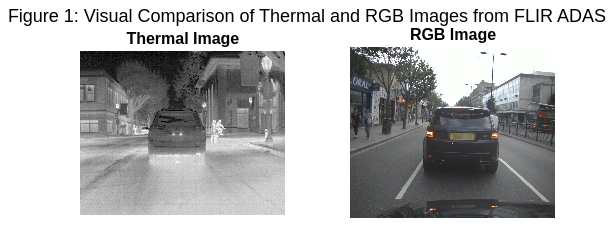

% Paths to example images
thermalPath = './Data/Compare_rgb_vs_thermal/image_THERMAL.jpg';
rgbPath     = './Data/Compare_rgb_vs_thermal/image_RGB.jpg';

% Read images
imgThermal = imread(thermalPath);
imgRGB     = imread(rgbPath);

% Ensure thermal is single-channel
if size(imgThermal,3) > 1
    imgThermal = rgb2gray(imgThermal);
end

% Display side by side
figure('Name','Thermal vs RGB Comparison','Position',[100 100 1000 400]);

subplot(1,2,1);
imshow(imgThermal);
title('Thermal Image','FontSize',12);

subplot(1,2,2);
imshow(imgRGB);
title('RGB Image','FontSize',12);

sgtitle('Figure 1: Visual Comparison of Thermal and RGB Images from FLIR ADAS','FontSize',14);

Before designing and training the object detection architecture, it is essential to understand the underlying data distribution. The FLIR ADAS dataset provides annotations in the standard MS-COCO JSON format and is pre-divided into three dedicated splits: Training, Validation, and Testing. Each split is stored in a separate folder and contains a `coco.json` file with the corresponding image metadata and bounding box annotations. The script below loads each split, parses the COCO annotations, and computes the number of images per split along with their relative proportions. The resulting distribution is summarised in Table 1.

%% Define Dataset Paths and Splits
datasetPaths = {'./Data/images_thermal_train', './Data/images_thermal_val', './Data/video_thermal_test'};
splitNames = {'Train', 'Validation', 'Test'};

%% Read Categories from the Training Dataset
cocoPath = fullfile(datasetPaths{1}, 'coco.json');
cocoData = jsondecode(fileread(cocoPath)); 

numClasses = length(cocoData.categories); 
classNames = strings(1, numClasses);
classIDs = zeros(1, numClasses);

for i = 1:numClasses
    classNames(i) = cocoData.categories(i).name;
    classIDs(i) = cocoData.categories(i).id;
end

numImagesPerSplit = zeros(1, length(datasetPaths));
countsPerSplit = zeros(numClasses, length(datasetPaths));

%% Process Each Dataset Split
for d = 1:length(datasetPaths)
    cocoPath = fullfile(datasetPaths{d}, 'coco.json');    
    cocoData = jsondecode(fileread(cocoPath)); 
    
    numImagesPerSplit(d) = length(cocoData.images);
    
    if d == 1
        numImgs   = length(cocoData.images);
        filenames   = cell(numImgs, 1);
        peopleBoxes  = cell(numImgs, 1);
        vehicleBoxes = cell(numImgs, 1);

        imageIDList = zeros(numImgs, 1);
        for k = 1:numImgs
            filenames{k}   = fullfile(datasetPaths{1}, cocoData.images(k).file_name);
            imageIDList(k) = cocoData.images(k).id;
        end
    end

    lowerClassNames = lower(classNames);
    targetClass1 = "person";
    targetClass2 = ["car", "motorcycle", "bus", "train", "truck", "other vehicle"];

    annotations = cocoData.annotations;
    for i = 1:length(annotations)
        if iscell(annotations)
            ann = annotations{i};
        else
            ann = annotations(i);
        end
        
        idx = find(classIDs == ann.category_id);
        if ~isempty(idx)
            countsPerSplit(idx, d) = countsPerSplit(idx, d) + 1;
        end

        % Store bounding boxes for train split visualization
        if d == 1
            catName = lower(classNames(idx));
            imgIdx  = find(imageIDList == ann.image_id, 1);
            bbox    = ann.bbox; % [x, y, w, h]

            if catName == targetClass1
                peopleBoxes{imgIdx} = [peopleBoxes{imgIdx}; bbox];
            elseif any(catName == targetClass2)
                vehicleBoxes{imgIdx} = [vehicleBoxes{imgIdx}; bbox];
            end
        end
    end
end

% Number and Percentage of Images per Split
totalImages = sum(numImagesPerSplit);

pcts = arrayfun(@(x) sprintf('%.2f%%', (x/totalImages)*100), numImagesPerSplit, 'UniformOutput', false);

T_splits = table(splitNames', numImagesPerSplit', pcts', ...
    'VariableNames', {'Split', 'N_Images', 'Percentage'});

disp('Table 1: Image Count and Percentage by Dataset Split');

Table 1: Image Count and Percentage by Dataset Split


disp(T_splits);

        Split         N_Images    Percentage
    ______________    ________    __________

    {'Train'     }     10742      {'68.70%'}
    {'Validation'}      1144      {'7.32%' }
    {'Test'      }      3749      {'23.98%'}



The data distribution is for the whole dataset:

- Training Set: 10,742 images (68.70%)

- Validation Set: 1,144 images (7.32%)

- Testing Set: 3,749 images (23.98%)

This distribution follows standard deep learning practice, allocating the majority of the data to training while reserving a substantial portion for final evaluation. The test set, comprising approximately 24% of the total data, provides a sufficiently large and unseen sample to produce reliable performance estimates. The validation set, although smaller, is used exclusively during training to monitor generalisation and guide hyperparameter tuning.

### 2.2 Category Analysis

The FLIR ADAS dataset originally contains a large number of annotated categories, however many of these have zero instances across all splits and are therefore disregarded. Table 2 presents only the 16 categories that have at least one annotated instance in the dataset.

% Full Category Table with categories with at least 1 instance
validIdx = any(countsPerSplit > 0, 2);

T_categories = table(...
    classNames(validIdx)', ...
    classIDs(validIdx)', ...
    countsPerSplit(validIdx, 1), ...
    countsPerSplit(validIdx, 2), ...
    countsPerSplit(validIdx, 3), ...
    'VariableNames', {'Category', 'ID', 'Train', 'Val', 'Test'});

disp('Table 2: All Categories with Non-Zero Instance Counts');

Table 2: All Categories with Non-Zero Instance Counts


disp(T_categories);

       Category        ID    Train    Val     Test 
    _______________    __    _____    ____    _____

    "person"            1    50478    4470    12323
    "bike"              2     7237     170      113
    "car"               3    73623    7133    30517
    "motor"             4     1116      55     3314
    "bus"               6     2245     179        0
    "train"             7        5       0        0
    "truck"             8      829      46     2634
    "light"            10    16198    2005     6758
    "hydrant"          11     1095      94      277
    "sign"             12    20770    2472     5660
    "dog"              17        4       0       25
    "deer"             18        8       0        0
    "skateboard"       37       29       3        0
    "stroller"         73       15       6       

As shown in Table 2, the dataset includes 16 active categories: Person, Bike, Car, Motor, Bus, Train, Truck, Light, Hydrant, Sign, Dog, Deer, Skateboard, Stroller, Scooter, and Other Vehicle. A clear class imbalance is visible since the classes Person and Car dominate across all splits, while categories such as Train, Dog, Deer, Skateboard, Stroller, and Scooter have very few instances, particularly in the validation and test sets.

In line with the objectives of Topic A3, which focuses on detecting pedestrians and vehicles in real driving scenarios, the dataset is filtered to retain only the 7 most relevant categories: Person, Car, Motorcycle, Bus, Train, Truck, and Other Vehicle. Categories unrelated to road safety such as Traffic Light, Fire Hydrant, Street Sign, and animals are excluded from the detection pipeline.

### 2.3 Target Class Selection

As evidenced by Table 2, the dataset exhibits a significant class imbalance. Person and Car account for the vast majority of annotated instances, while categories such as Train, Motorcycle, and Other Vehicle are considerably underrepresented. Training a multi-class detector on this raw distribution would likely result in a model biased towards the dominant classes, with poor generalisation on the minority ones.

To address this, the detection task is reformulated into two well-balanced and semantically meaningful classes:

- Class 1 **(People):** directly mapped from the Person category, representing all pedestrians in the scene.

- Class 2 **(Vehicles):** formed by merging Car, Motorcycle, Bus, Train, Truck, and Other Vehicle into a single class. This grouping is justified by the shared detection objective for identifying any road vehicle ensuring that the combined class has sufficient training examples for reliable detection.

The instance counts for the selected categories are presented in Table 3. This grouping strategy ensures the model focuses on the objects most critical to road safety, while mitigating the effects of class imbalance through category consolidation.

% Define target categories and display instance counts
targetCategories = ["person", "car", "motor", "bus", "train", "truck", "other vehicle"];

catLabels  = strings(length(targetCategories), 1);
trainCounts = zeros(length(targetCategories), 1);
valCounts   = zeros(length(targetCategories), 1);
testCounts  = zeros(length(targetCategories), 1);

for c = 1:length(targetCategories)
    idxCat = find(lowerClassNames == targetCategories(c));
    if ~isempty(idxCat)
        catLabels(c)   = classNames(idxCat);
        trainCounts(c) = countsPerSplit(idxCat, 1);
        valCounts(c)   = countsPerSplit(idxCat, 2);
        testCounts(c)  = countsPerSplit(idxCat, 3);
    end
end

T_target = table(catLabels, trainCounts, valCounts, testCounts, ...
    'VariableNames', {'Category', 'Train', 'Val', 'Test'});

disp('Table 3: Instance Counts for Target Categories');

Table 3: Instance Counts for Target Categories


disp(T_target);

       Category        Train    Val     Test 
    _______________    _____    ____    _____

    "person"           50478    4470    12323
    "car"              73623    7133    30517
    "motor"             1116      55     3314
    "bus"               2245     179        0
    "train"                5       0        0
    "truck"              829      46     2634
    "other vehicle"     1373      63      696



### 2.4 Data Preparation

While the full FLIR ADAS dataset provides over 14,000 training images, training on the complete dataset imposes significant computational demands in terms of memory, processing time, and GPU requirements. Given the hardware constraints and in the interest of rapid iteration during model development and hyperparameter tuning, a representative 5% subset was sampled from each split.

This decision is supported by several practical arguments. First, the dataset is heavily dominated by two classes (Person and Vehicle), meaning that even a 5% sample retains a statistically representative distribution of instances across classes. Second, reducing the dataset size allows for faster training cycles, making it feasible to experiment with different architectures, augmentation strategies, and training parameters within a reasonable timeframe.

The subsampling is performed by the auxiliary function `aux_subsampleDataset.m`, which randomly samples a specified fraction of images from each split while preserving the original folder structure and COCO annotation format. The resulting subsets are saved to new folders suffixed with `_subset`.

subsetFraction = 0.05;   % 5% of each split
rngSeed        = 42;     % for reproducibility

splitPaths = {
    './Data/images_thermal_train', ...
    './Data/images_thermal_val', ...
    './Data/video_thermal_test'
};

subsetPaths = cell(size(splitPaths));
for d = 1:numel(splitPaths)
    subsetPaths{d} = aux_subsampleDataset(splitPaths{d}, subsetFraction, rngSeed);
    fprintf('Subset created: %s\n', subsetPaths{d});
end

   Copied 0 / 537 images
   [./Data/images_thermal_train] 10742 → 537 images (5%) saved to ./Data/images_thermal_train_subset


Subset created: ./Data/images_thermal_train_subset


   Copied 0 / 57 images
   [./Data/images_thermal_val] 1144 → 57 images (5%) saved to ./Data/images_thermal_val_subset


Subset created: ./Data/images_thermal_val_subset


   Copied 0 / 187 images
   [./Data/video_thermal_test] 3749 → 187 images (5%) saved to ./Data/video_thermal_test_subset


Subset created: ./Data/video_thermal_test_subset



% Stats table
splitLabels  = {'Train'; 'Validation'; 'Test'};
fullCounts   = numImagesPerSplit';
subsetCounts = zeros(3,1);
for d = 1:3
    subCocoPath = fullfile(subsetPaths{d}, 'coco.json');
    subCoco     = jsondecode(fileread(subCocoPath));
    subsetCounts(d) = numel(subCoco.images);
end
retained = arrayfun(@(a,b) sprintf('%.1f%%', 100*a/b), ...
                    subsetCounts, fullCounts, 'UniformOutput', false);

T_subset = table(splitLabels, fullCounts, subsetCounts, retained, ...
    'VariableNames', {'Split','Full_Dataset','Subset','Retained'});

disp('Table 4: Full Dataset vs. Subset Size per Split');

Table 4: Full Dataset vs. Subset Size per Split


disp(T_subset);

        Split         Full_Dataset    Subset    Retained
    ______________    ____________    ______    ________

    {'Train'     }       10742         537      {'5.0%'}
    {'Validation'}        1144          57      {'5.0%'}
    {'Test'      }        3749         187      {'5.0%'}



The consolidated class distribution of the dataset is visualized in Figure 2. The bar chart presents the total number of annotated instances for each class across the training, validation, and test splits. Overall, the data from the training subset contains 2728 instances of People and 6121 instances of Vehicles, indicating a higher representation of vehicles relative to pedestrians. This distribution provides ample data for both classes. Visualizing the consolidated distribution ensures that the selected splits contain sufficient examples to train and evaluate the model effectively for detecting both pedestrians and vehicles.

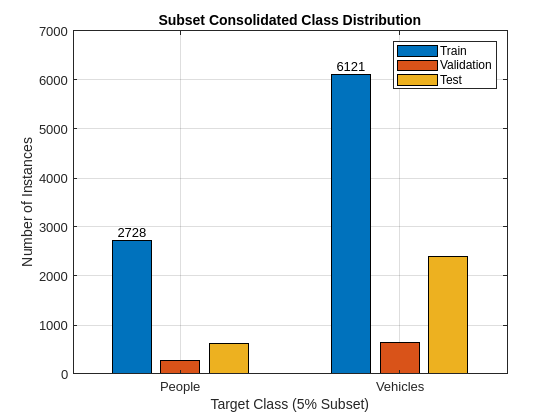

% 1. Extract Class Distributions from Subset COCO files
% Assuming: Category 1 = People, Categories 2+ = Vehicles
subTrainCounts = [0, 0]; % [People, Vehicles]
subValCounts   = [0, 0];
subTestCounts  = [0, 0];

subsetCountsArray = {subTrainCounts, subValCounts, subTestCounts};

for d = 1:3
    subCocoPath = fullfile(subsetPaths{d}, 'coco.json');
    subCoco     = jsondecode(fileread(subCocoPath));
    
    % Get all category IDs for annotations in this subset
    if isfield(subCoco, 'annotations')
        annCatIds = [subCoco.annotations.category_id];
        
        % Count People (ID 1)
        peopleCount = sum(annCatIds == 1);
        % Count Vehicles (IDs > 1)
        vehicleCount = sum(annCatIds > 1);
        
        subsetCountsArray{d} = [peopleCount, vehicleCount];
    end
end

% Re-assign for plotting
finalTrainSub = subsetCountsArray{1};
finalValSub   = subsetCountsArray{2};
finalTestSub  = subsetCountsArray{3};

% 2. Visualization of Subset Class Distribution
figure('Name', 'Figure 2: Subset Class Distribution (5%)');
% Transpose to group by Split on the X-axis or by Class
% Here we keep your format: X-axis = Classes
b2 = bar([finalTrainSub; finalValSub; finalTestSub]', 'grouped');

set(gca, 'xticklabel', {'People', 'Vehicles'});
xlabel('Target Class (5% Subset)');
ylabel('Number of Instances');
title('Subset Consolidated Class Distribution');
legend({'Train', 'Validation', 'Test'});
grid on;

% Add text labels on top of bars for clarity
xtips1 = b2(1).XEndPoints;
ytips1 = b2(1).YData;
labels1 = string(ytips1);
text(xtips1, ytips1, labels1, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');

To better understand the dataset imagery, the plotted examples demonstrate that the scale, aspect ratio, and visual density of the bounding boxes vary significantly depending on the environment. Figure 3 illustrates two representative scenarios: a road segment containing two vehicles, and an instance featuring a single vehicle alongside a pedestrian.

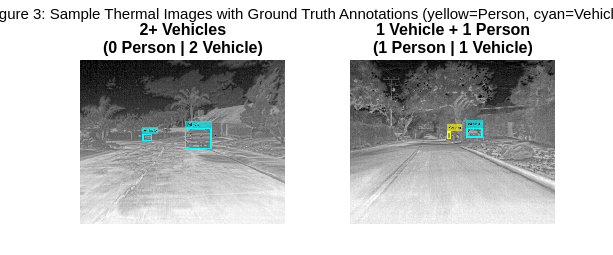

% Load subset training annotations
subCocoPath = fullfile(subsetPaths{1}, 'coco.json');
subCoco     = jsondecode(fileread(subCocoPath));

% Build image_id -> annotations map
annByImage = containers.Map('KeyType','double','ValueType','any');
for k = 1:numel(subCoco.annotations)
    if iscell(subCoco.annotations); ann = subCoco.annotations{k};
    else;                           ann = subCoco.annotations(k); end
    id = double(ann.image_id);
    if ~isKey(annByImage, id); annByImage(id) = {}; end
    annByImage(id) = [annByImage(id), {ann}];
end

% Build category_id -> label string
catLabels = containers.Map('KeyType','double','ValueType','char');
for i = 1:numel(subCoco.categories)
    if iscell(subCoco.categories); cat = subCoco.categories{i};
    else;                          cat = subCoco.categories(i); end
    name = lower(cat.name);
    if strcmp(name, 'person')
        catLabels(double(cat.id)) = 'Person';
    elseif any(strcmp(name, ["car","motor","bus","train","truck","other vehicle"]))
        catLabels(double(cat.id)) = 'Vehicle';
    else
        catLabels(double(cat.id)) = cat.name;
    end
end

% Find images matching specific criteria
% Slot 1: 2+ vehicles
% Slot 2: exactly 1 vehicle, 1 person

slot = cell(2, 1);   

for i = 1:numel(subCoco.images)
    if iscell(subCoco.images); imgInfo = subCoco.images{i};
    else;                      imgInfo = subCoco.images(i); end

    [img, labels, bboxes] = aux_load_annotaded_image(imgInfo, subsetPaths{1}, annByImage, catLabels);
    if isempty(img) || isempty(bboxes); continue; end

    nPerson  = sum(strcmp(labels, 'Person'));
    nVehicle = sum(strcmp(labels, 'Vehicle'));

    % Slot 1 — 2+ vehicles
    if isempty(slot{1}) && nVehicle >= 2
        slot{1} = {img, labels, bboxes}; continue;
    end
    % Slot 2 — exactly 1 vehicle + 1 person
    if isempty(slot{2}) && nVehicle == 1 && nPerson == 1
        slot{2} = {img, labels, bboxes}; continue;
    end

    % Stop once both slots are filled
    if ~any(cellfun(@isempty, slot)); break; end
end

% Plot side-by-side (1x2 grid)
titles = {
    '2+ Vehicles', ...
    '1 Vehicle + 1 Person'
};

figure('Name', 'Sample Ground Truth', 'Position', [100 100 1200 500]);

for s = 1:2
    if isempty(slot{s})
        fprintf('   Warning: no image found for slot %d\n', s);
        continue;
    end

    img    = slot{s}{1};
    labels = slot{s}{2};
    bboxes = slot{s}{3};

    for j = 1:size(bboxes, 1)
        color = 'yellow';
        if strcmp(labels{j}, 'Vehicle'); color = 'cyan'; end
        % Bumped LineWidth to 4 for bolder/bigger boxes
        img = insertObjectAnnotation(img, 'rectangle', bboxes(j,:), ...
            labels{j}, 'Color', color, 'LineWidth', 4, 'FontSize', 12);
    end

    nP = sum(strcmp(labels, 'Person'));
    nV = sum(strcmp(labels, 'Vehicle'));

    % 1 row, 2 columns, position s
    subplot(1, 2, s); 
    imshow(img);
    title(sprintf('%s\n(%d Person | %d Vehicle)', titles{s}, nP, nV), 'FontSize', 12);
end

sgtitle('Figure 3: Sample Thermal Images with Ground Truth Annotations (yellow=Person, cyan=Vehicle)');

Visualizing these ground truth annotations highlights the inherent complexities of the data, particularly regarding the sizes of the target objects. As demonstrated in the second sample of Figure 3, the bounding boxes for objects can be exceedingly small, illustrating how scale varies significantly based on distance from the camera. Identifying these challenges early on is essential for designing an effective object detection pipeline.

## 3. Object Detection Architectures

Modern object detection methods are mainly based on deep learning, which allows models to automatically learn relevant features from data. These methods are generally divided into two types: two-stage detectors, which first generate candidate regions and then classify them, and single-stage detectors, which perform detection in a single step.

In this project, a single-stage approach is adopted due to its computational efficiency and suitability for real-time applications such as ADAS. Specifically, the You Only Look Once (YOLOv2) architecture is selected as the foundation for both the baseline and optimised models, as it offers a strong balance between detection speed and accuracy while being natively supported within the MATLAB Deep Learning Toolbox.

This section details the two detection pipelines developed in this project the baseline and the optimised champion model describing their respective architectural choices, training strategies, and the design decisions that differentiate them.

### 3.1. Baseline Deep Learning Model

To overcome the spatial and contextual limitations of classical machine learning approaches, a baseline deep learning model was implemented. The chosen framework, YOLOv2, is a highly efficient, single-stage object detection architecture that diverges from traditional methods by formulating detection as a single regression problem, predicting bounding box coordinates and class probabilities simultaneously across the entire image. To maintain code modularity, the model was trained using an external auxiliary file `aux_model_baseline.m.`

#### 3.1.1. Transfer Learning and Backbone Model 

The YOLOv2  architecture is a single-stage object detection model that performs object localization and classification in a single forward pass of the network. Instead of analysing different regions of an image separately, YOLO divides the image into a grid and directly predicts bounding boxes, confidence scores, and class probabilities for each cell. This unified approach makes it significantly faster than traditional methods, while still maintaining good detection performance, which is particularly important for real-time applications such as ADAS.

To function effectively, the YOLO architecture relies on a foundational feature extractor, often referred to as a backbone neural network. This predetermined base network is responsible for processing the raw input pixels into rich, hierarchical feature maps that encode the structural and semantic representations of the scene, which the YOLO layers then use to make their spatial predictions.

To improve performance and reduce training time, transfer learning is applied by using a backbone network pre-trained on a large dataset. In this project, SqueezeNet was selected as the backbone network for the baseline model. As an initial iteration of a simple detection architecture, SqueezeNet provides a lightweight and computationally efficient foundation. Its reduced number of parameters enables faster training and experimentation, making it a suitable choice for validating the detection pipeline before exploring more complex architectures.

#### **3.1.2. Data-Driven Anchor Box Estimation**

A critical component of single-stage object detectors like YOLOv2 is the use of anchor boxes (also known as prior boxes). Instead of forcing the neural network to predict arbitrary bounding box dimensions from scratch, the network predicts spatial offsets relative to a set of predefined reference boxes. These reference boxes represent the typical scales and aspect ratios of the objects the model is expected to detect (e.g., a tall, narrow box for a pedestrian, or a short, wide box for a car). While anchor boxes can be defined manually, assigning generic shapes often leads to sub-optimal training and poor detection localization. To address this, the implementation dynamically estimated the anchor boxes directly from the training data. For the initial iteration, the number of anchors was selected to be 5 since it captures a good trade-off between bounding box recall and model complexity.

#### **3.1.3. **Data Transformation and Formatting

A significant architectural constraint when utilizing transfer learning with established models like SqueezeNet is the input dimensionality requirement. Because the backbone network was pre-trained on the ImageNet dataset, its initial convolutional layers strictly expect a three-channel (RGB) input volume. However, the FLIR ADAS dataset used for this analysis consists of single-channel thermal grayscale imagery.

To bridge this dimensional gap without permanently altering the underlying dataset files, an on-the-fly data transformation pipeline was implemented using MATLAB's datastore framework. A custom transformation function was defined utilizing the repmat operation, which dynamically duplicates the single-channel thermal matrix across three spatial dimensions $ 1 \times 1 \times 3$ as the images are loaded into memory. This function was subsequently mapped to the combined image and bounding box datastores using the transform method. This approach ensures the thermal data is seamlessly projected into a pseudo-RGB format compatible with SqueezeNet’s input layer, while preserving computational efficiency and minimizing disk storage overhead.

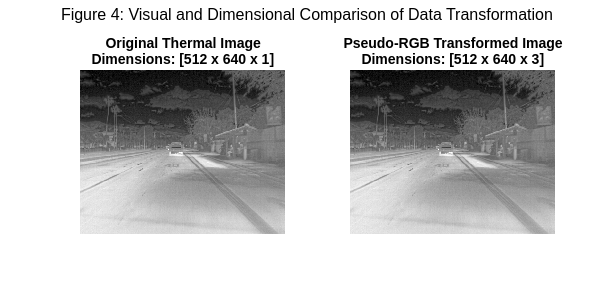

% 1. Load a single sample thermal image (1-channel)
subCocoPath = fullfile(subsetPaths{1}, 'coco.json');
subCoco = jsondecode(fileread(subCocoPath));
sampleImgPath = fullfile(subsetPaths{1}, subCoco.images(1).file_name);
imgGray = imread(sampleImgPath);

% Ensure it's actually 1-channel for the demonstration
if size(imgGray, 3) == 3
    imgGray = rgb2gray(imgGray); 
end

% 2. Apply the repmat transformation (3-channel)
imgRGB = repmat(imgGray, [1 1 3]);

% 3. Plotting
figure('Name', 'Dimensionality Transformation', 'Position', [100, 100, 800, 400]);

% Plot original 1-channel
subplot(1, 2, 1);
imshow(imgGray);
dimGray = sprintf('%d x %d x %d', size(imgGray, 1), size(imgGray, 2), size(imgGray, 3));
title(sprintf('Original Thermal Image\nDimensions: [%s]', dimGray), 'FontSize', 11);

% Plot transformed 3-channel
subplot(1, 2, 2);
imshow(imgRGB);
dimRGB = sprintf('%d x %d x %d', size(imgRGB, 1), size(imgRGB, 2), size(imgRGB, 3));
title(sprintf('Pseudo-RGB Transformed Image\nDimensions: [%s]', dimRGB), 'FontSize', 11);

sgtitle('Figure 4: Visual and Dimensional Comparison of Data Transformation');

To visually validate this transformation, a sample from the dataset was plotted before and after the operation (Figure 4). As expected to the human eye, both images appear identical as standard grayscale photographs. However, as demonstrated by the accompanying tensor dimensions, the original thermal image is a 2D matrix $H \times W \times 1
$, whereas the transformed image is a 3D tensor $$H \times W \times 3$
$. Because the Red, Green, and Blue channels contain identical intensity values, no artificial color is introduced; instead, the volumetric requirement of the SqueezeNet input layer is satisfied without altering the semantic meaning of the thermal signatures.

#### **3.1.4. Training Hyperparameter Selection**

The final stage of configuring the baseline model involved defining the training hyperparameters. The network was trained using the Stochastic Gradient Descent with Momentum (SGDM) optimizer, a widely utilized algorithm that provides stable convergence for complex object detection tasks.

To align with the project's objective of evaluating feasibility and exploring approaches rather than immediately achieving a definitive solution, the hyperparameters were balanced to ensure efficient training while still capturing meaningful learning trends. The maximum number of epochs was set to 30, which provides sufficient iterations to establish a performance benchmark without excessive computational cost. A mini-batch size of 8 was selected to balance memory constraints with gradient stability during backpropagation.

Furthermore, the initial learning rate was set to $1 \times 10^{-3}$. This conservative learning rate allows the newly initialized YOLO layers to adapt to the dataset without aggressively overwriting the pre-trained feature extraction weights of the SqueezeNet backbone. Finally, the validation datastore was integrated into the training loop and evaluated every 50 iterations. This frequent validation allowed for active monitoring of the loss curves to ensure the model was generalizing to unseen thermal data rather than overfitting to the training set.

### 3.2. Optimized Deep Learning Model

Following the evaluation of the baseline architecture, a series of algorithmic optimizations and data augmentation strategies were implemented to address the observed limitations, specifically targeting the model's generalization capabilities and localization accuracy on thermal imagery. This iteration refines the training pipeline and hyperparameters.

#### **3.2.1. Advanced Data Augmentation Strategy**

One of the primary challenges with the baseline model was its susceptibility to overfitting the training dataset, a common issue when training deep networks on specialized domains like thermal imaging. To artificially expand the dataset and improve the model's robustness, an active data augmentation pipeline was integrated directly into the `imageDatastore` using a custom transformation function. During training, the following stochastic augmentations were applied on-the-fly:

- **Spatial Invariance:** Random horizontal flipping (with a 50% probability) was applied, with corresponding geometric transformations made to the ground truth bounding boxes. This prevents the model from memorizing specific road layouts or directional biases.

- **Thermal Profile Jittering:** To simulate varying environmental temperatures and sensor calibration differences, random brightness and contrast jittering were introduced. By scaling the pixel intensities relative to the image mean, the model learns to detect the structural silhouettes of pedestrians and vehicles rather than relying on absolute pixel intensity values.

- **Dynamic Scaling:** Images were dynamically resized with mathematically scaled bounding boxes, ensuring consistency with the network's input layer while preserving spatial ground truth accuracy.

To ensure a fair and scientifically valid evaluation, these augmentations were strictly isolated to the training datastore. The validation and testing datastores received only the deterministic preprocessing (grayscale-to-RGB expansion and resizing). 

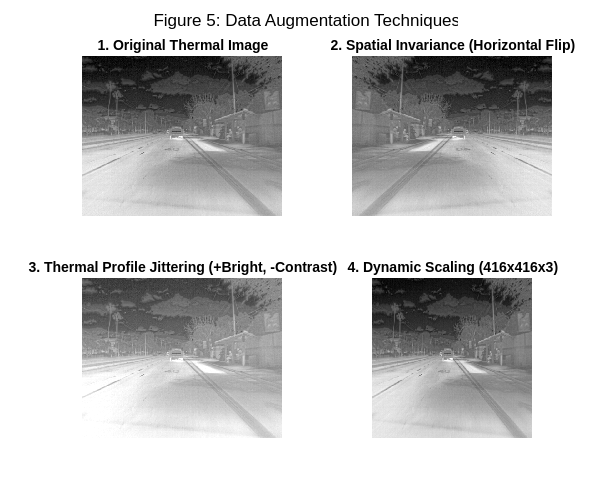

% Load a sample image from trainData
subCocoPath = fullfile(subsetPaths{1}, 'coco.json');
subCoco = jsondecode(fileread(subCocoPath));
sampleImgPath = fullfile(subsetPaths{1}, subCoco.images(1).file_name);
imgOrig = imread(sampleImgPath);


if size(imgOrig, 3) == 1
    imgOrig = repmat(imgOrig, [1 1 3]); % Convert to pseudo-RGB
end
imgOrig = im2single(imgOrig);

% Transformation A: Original
img1 = imgOrig;

% Transformation B: Horizontal Flip
imgFlip = fliplr(imgOrig);
img2    = imgFlip;

% Transformation C: Thermal Jitter (Brightness/Contrast)
brightFactor   = 1.3; % +30% brightness
contrastFactor = 0.7; % -30% contrast
imgJitter      = imgOrig * brightFactor;
meanVal        = mean(imgJitter(:));
imgJitter      = (imgJitter - meanVal) * contrastFactor + meanVal;
imgJitter      = min(max(imgJitter, 0), 1); % Clamp values to [0,1]
img3           = imgJitter;

% Transformation D: Dynamic Scaling (Resize to 416x416)
targetSize = [416, 416];
imgScale   = imresize(imgOrig, targetSize);
img4       = imgScale;

% Plotting the 2x2 Grid
figure('Name', 'Augmentation Pipeline', 'Position', [100, 100, 1000, 800]);

subplot(2, 2, 1);
imshow(img1);
title('1. Original Thermal Image', 'FontSize', 11);

subplot(2, 2, 2);
imshow(img2);
title('2. Spatial Invariance (Horizontal Flip)', 'FontSize', 11);

subplot(2, 2, 3);
imshow(img3);
title('3. Thermal Profile Jittering (+Bright, -Contrast)', 'FontSize', 11);

subplot(2, 2, 4);
imshow(img4);
title(sprintf('4. Dynamic Scaling (%dx%dx3)', targetSize(2), targetSize(1)), 'FontSize', 11);

sgtitle('Figure 5: Data Augmentation Techniques');

To visually verify the integrity of the data augmentation pipeline, particularly the geometric transformations applied to the bounding boxes, a sample image was processed through the individual augmentation steps (Figure 5). As demonstrated, the horizontal flip accurately mirrors the image. The thermal profile jittering successfully shifts the overall intensity and contrast, and the dynamic scaling correctly maps the aspect ratio of the image to the new $416 \times 416
$ input resolution.

#### **3.2.2. Algorithmic and Hyperparameter Enhancements**

The training hyperparameters were comprehensively reconfigured to facilitate a deeper and more stable convergence:

- **Anchor Box Expansion:** The number of K-means estimated anchor boxes was increased from 5 to 7. This provides the YOLO layers with a higher degree of spatial diversity, allowing for tighter initial bounding box approximations for both highly occluded distant objects and large foreground vehicles.

- **Optimizer Transition:** The optimizer was switched from SGDM to the Adam (Adaptive Moment Estimation) algorithm. Adam computes individual adaptive learning rates for different parameters, which is particularly beneficial when fine-tuning a pre-trained network on a highly varied dataset.

- **Learning Rate Scheduling:** The initial learning rate was reduced to $1 \times 10^{-4}$ to prevent catastrophic forgetting of the pre-trained ImageNet weights. Furthermore, a piecewise learning rate schedule was introduced, configured to drop the learning rate by a factor of 0.5 every 15 epochs. This allows the model to make rapid adjustments early in training and fine-tune its decision boundaries as it approaches convergence.

- **Regularization and Batch Stability:** L2 Regularization $1 \times 10^{-4}$ was added to penalize excessively large network weights, further mitigating overfitting. Additionally, the mini-batch size was doubled from 8 to 16, resulting in smoother, more representative gradient updates during backpropagation. To accommodate the lower learning rate and piecewise schedule, the total training duration was extended from 30 to 40 epochs.

#### 3.2.3 Backbone Model Choise

The choice of backbone network is a key factor in the performance of an object detection system, as it directly influences the quality of feature extraction and the computational efficiency of the model. For the improvement and further testing, two backbone architectures were considered: *SqueezeNet* and *GoogLeNet*.

Despite having significantly fewer parameters than deeper networks, *SqueezeNet* is capable of extracting meaningful visual features, making it a strong candidate for lightweight and real-time applications. *GoogLeNet*, on the other hand, offers a deeper architecture with Inception modules that capture multi-scale features, which can improve detection performance in certain scenarios. However, its higher computational requirements and longer training times may make it less suitable for contexts that demand efficiency and real-time processing. To maintain code modularity, the models were trained using an external auxiliary files `aux_model_improved_googlenet.m `and `aux_model_improved_squeezenet.m.`

## 4. Results and Discussion

The following section presents a comprehensive evaluation of the developed object detection pipelines. The assessment is divided into two primary stages: the training and testing of a Baseline Model as detailed in the previous section, and the subsequent training and testing of an Improved Model featuring architectural refinements and data augmentation.

### 4.1. Evaluation Metrics

To objectively quantify the performance of the trained object detection pipelines, a standard set of computer vision evaluation metrics was utilized. When the models were run against the unseen testing datastore, predictions were filtered using a baseline detection confidence threshold of 0.3. The resulting bounding boxes were evaluated using the following metrics:

- **Intersection over Union (IoU):** The foundational metric used to determine if a predicted bounding box is a true positive. It calculates the ratio of the overlapping area between the predicted box and the ground truth box over their combined total area. By default, MATLAB's evaluation function requires an IoU of at least 0.5 (50% overlap) for a detection to be considered correct.

- **Precision:** The ratio of true positive detections to the total number of predicted bounding boxes. 

- **Recall:** The ratio of true positive detections to the total number of actual ground truth objects in the dataset. 

- **Average Precision (AP):** A comprehensive metric evaluated for each individual class (`person` and `vehicle`). It is calculated as the area under the Precision-Recall curve, providing a single number that encapsulates the model's ability to balance precision and recall across all confidence thresholds.

- **Mean Average Precision (mAP):** The primary benchmark for overall system performance, calculated as the unweighted mean of the Average Precision scores across all evaluated classes.

These metrics ensure that the models are not just evaluated on their ability to draw bounding boxes, but on their precise spatial localization and classification accuracy on the thermal imagery.

### 4.2. Baseline Deep Learning Model

The baseline model, utilizing a YOLOv2 architecture with a SqueezeNet backbone, was evaluated to establish a performance benchmark. This initial iteration was trained for 30 epochs without data augmentation to identify the raw capability of the transfer learning approach on thermal imagery.

apResults = readtable('./Output/baseline/ap_results.csv');
mAP_baseline = mean(apResults.AP);

fprintf('Table 5: Baseline Model Performance\n');

Table 5: Baseline Model Performance


disp(apResults);

       Class          AP   
    ___________    ________

    {'person' }    0.027998
    {'vehicle'}    0.083871



fprintf('Total Mean Average Precision (mAP): %.4f\n', mAP_baseline);

Total Mean Average Precision (mAP): 0.0559


The numerical results indicate a significant performance gap between classes. The Vehicle class achieves nearly four times higher average precision than the Person class, owing to its larger and more consistent thermal signatures. Pedestrian detection presents a greater challenge for the shallow SqueezeNet backbone due to the smaller spatial scale and lower contrast of people in the thermal domain. Although the results are low in absolute terms, they establish the performance benchmark from which subsequent improvements are made.

To evaluate the learning behaviour, training loss and Root Mean Squared Error (RMSE) were monitored and plotted in Figure 6. Training loss steadily declined throughout the 30 epochs, confirming successful weight optimisation. A widening gap between training and validation loss in the later stages of training suggests the onset of overfitting, which motivates the introduction of data augmentation in the improved model. Training RMSE also trended downward, indicating progressively improved bounding box localisation, though the final values suggest that further refinement remains possible.

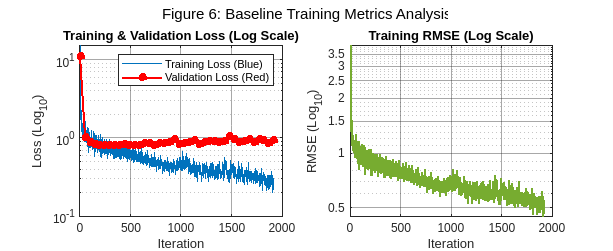

tLoss = readtable('./Output/baseline/training_TrainingLoss.csv');
vLoss = readtable('./Output/baseline/training_ValidationLoss.csv');
tRMSE = readtable('./Output/baseline/training_TrainingRMSE.csv');

% Clean NaN values
vLoss = vLoss(~isnan(vLoss.ValidationLoss), :);

figure('Name', 'Baseline Training Analysis', 'Position', [100, 100, 1100, 450]);

% Loss Plots - Log Scale
subplot(1,2,1);
valIter = linspace(1, height(tLoss), height(vLoss));

% Training Loss in a clear Royal Blue
semilogy(tLoss.TrainingLoss, 'Color', [0 0.4470 0.7410], 'LineWidth', 1); 
hold on;

% Validation Loss in a bold Red with markers
semilogy(valIter, vLoss.ValidationLoss, 'r-o', 'LineWidth', 1.5, ...
    'MarkerSize', 5, 'MarkerFaceColor', 'r');

title('Training & Validation Loss (Log Scale)');
xlabel('Iteration'); ylabel('Loss (Log_{10})');
legend('Training Loss (Blue)', 'Validation Loss (Red)', 'Location', 'northeast');
grid on; set(gca, 'GridAlpha', 0.4);

% RMSE Plot - Log Scale
subplot(1,2,2);
semilogy(tRMSE.TrainingRMSE, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5);

title('Training RMSE (Log Scale)');
xlabel('Iteration'); ylabel('RMSE (Log_{10})');
grid on; set(gca, 'GridAlpha', 0.4);

sgtitle('Figure 6: Baseline Training Metrics Analysis');

The Precision-Recall curves in Figure 7 provide a granular view of the model’s detection efficacy across different confidence thresholds.

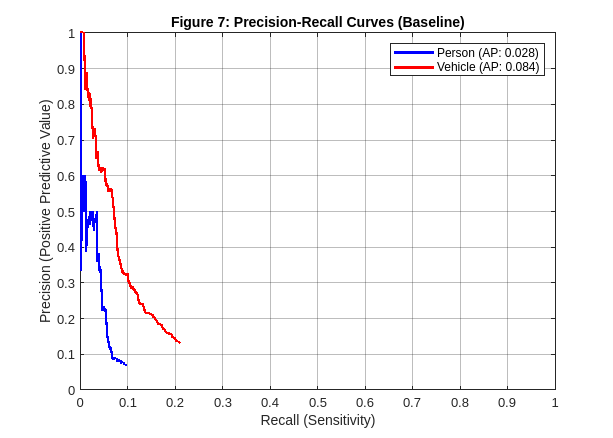

prPerson = readtable('./Output/baseline/pr_curve_person.csv');
prVehicle = readtable('./Output/baseline/pr_curve_vehicle.csv');

figure('Name', 'Baseline PR Curves', 'Position', [100, 100, 700, 500]);
plot(prPerson.Recall, prPerson.Precision, 'b-', 'LineWidth', 2); hold on;
plot(prVehicle.Recall, prVehicle.Precision, 'r-', 'LineWidth', 2);

% Labeling and Formatting
xlabel('Recall (Sensitivity)'); 
ylabel('Precision (Positive Predictive Value)');
title('Figure 7: Precision-Recall Curves (Baseline)');
legend(sprintf('Person (AP: %.3f)', 0.028), ...
       sprintf('Vehicle (AP: %.3f)', 0.084), ...
       'Location', 'northeast');

axis([0 1 0 1]);
grid on;
set(gca, 'GridAlpha', 0.3);

From the analysis of the plot in Figure 7, we notice that both curves truncate at recall <0.2, indicating a high rate of false negatives. The sharp initial precision drop reflects rapid false positive growth as recall increases, and the jagged person curve suggests instability in pedestrian detection. These low AP values confirm that raw transfer learning without data augmentation or architectural tuning is inadequate for reliable ADAS thermal vision.

### 4.3. Improved Deep Learning Models

Following the independent evaluation of the baseline and improved pipelines, a comparative analysis was performed to identify the Champion model configuration. This comparison focuses on the performance delta between the  GoogLeNet and SqueezeNet backbones when subjected to the same advanced augmentation and hyperparameter tuning. The improved 

resGoogLe   = readtable('./Output/improved_googlenet/ap_results_improved.csv');
resSqueeze  = readtable('./Output/improved_squeezenet/ap_results_improved.csv');

% Calculate mean Average Precision (mAP)
mAP_GoogLe  = mean(resGoogLe.AP);
mAP_Squeeze = mean(resSqueeze.AP);

% Prepare data for the final comparison table
rowNames      = [resSqueeze.Class; {'Mean (mAP)'}];
googLeScores  = [resGoogLe.AP; mAP_GoogLe];
squeezeScores = [resSqueeze.AP; mAP_Squeeze];

% Calculate Percentage Gain
percentGain = ((squeezeScores - googLeScores) ./ googLeScores) * 100;

% Construct the Final Comparison Table
comparisonTable = table(rowNames, googLeScores, squeezeScores, percentGain, ...
    'VariableNames', {'Object_Category', 'GoogLeNet_AP', 'SqueezeNet_Champion_AP', 'Performance_Gain_Percentage'});

% Display Results
disp('Table 6: Average Precision (AP) Comparison: GoogLeNet vs. SqueezeNet Champion');

Table 6: Average Precision (AP) Comparison: GoogLeNet vs. SqueezeNet Champion


disp(comparisonTable);

    Object_Category    GoogLeNet_AP    SqueezeNet_Champion_AP    Performance_Gain_Percentage
    _______________    ____________    ______________________    ___________________________

    {'person'    }      0.0033322             0.045207                     1256.7           
    {'vehicle'   }       0.022979              0.11981                      421.4           
    {'Mean (mAP)'}       0.013156              0.08251                     527.18           



Unexpectedly, the comparative analysis (Table 6) reveals that the SqueezeNet backbone achieved superior performance to the more complex GoogLeNet architecture, with a total mAP gain of 527%. This phenomenon can be attributed to the relationship between model capacity and dataset size. While GoogLeNet features a deeper hierarchy and Inception modules, its higher parameter count may lead to slight overfitting to the specific thermal signatures of the dataset. Therefore, SqueezeNet is selected as the Champion model for the continuation of this study.

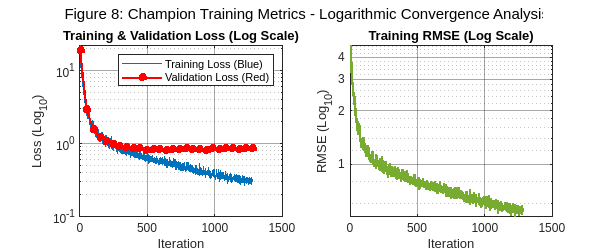

tLoss = readtable('./Output/improved_squeezenet/improved_training_TrainingLoss.csv');
vLoss = readtable('./Output/improved_squeezenet/improved_training_ValidationLoss.csv');
tRMSE = readtable('./Output/improved_squeezenet/improved_training_TrainingRMSE.csv');

% Clean NaN values
vLoss = vLoss(~isnan(vLoss.ValidationLoss), :);

figure('Name', 'Champion Training Analysis', 'Position', [100, 100, 1100, 450]);

% Loss Plots - Log Scale
subplot(1,2,1);
valIter = linspace(1, height(tLoss), height(vLoss));

% Training Loss 
semilogy(tLoss.TrainingLoss, 'Color', [0 0.4470 0.7410], 'LineWidth', 1); 
hold on;

% Validation Loss 
semilogy(valIter, vLoss.ValidationLoss, 'r-o', 'LineWidth', 1.5, ...
    'MarkerSize', 5, 'MarkerFaceColor', 'r');

title('Training & Validation Loss (Log Scale)');
xlabel('Iteration'); ylabel('Loss (Log_{10})');
legend('Training Loss (Blue)', 'Validation Loss (Red)', 'Location', 'northeast');
grid on; set(gca, 'GridAlpha', 0.4);

% RMSE Plot - Log Scale
subplot(1,2,2);
semilogy(tRMSE.TrainingRMSE, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5);

title('Training RMSE (Log Scale)');
xlabel('Iteration'); ylabel('RMSE (Log_{10})');
grid on; set(gca, 'GridAlpha', 0.4);

sgtitle('Figure 8: Champion Training Metrics - Logarithmic Convergence Analysis');

Figure 8 shows that the optimized SqueezeNet, using Adam and a piecewise learning rate schedule, achieves stable and efficient convergence. The training loss exhibits less oscillation than the baseline, reflecting effective navigation of the thermal loss surface. Validation loss closely tracks training loss, confirming that data augmentation prevented overfitting. On a logarithmic scale, training RMSE keeps steadily improving, even in final iterations, as the learning rate decays. Overall, the model reaches a superior local minimum, with robustness to the noise and low contrast of thermal imagery.

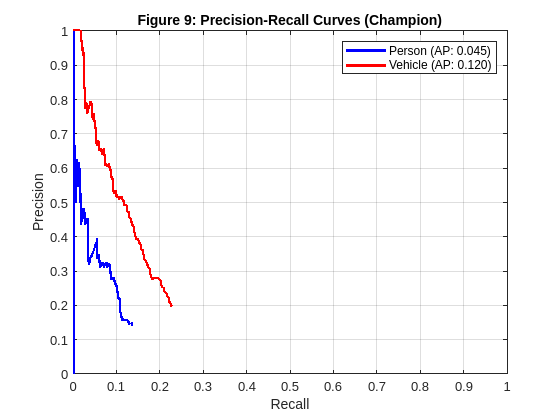

prPerson = readtable('./Output/improved_squeezenet/pr_curve_improved_person.csv');
prVehicle = readtable('./Output/improved_squeezenet/pr_curve_improved_vehicle.csv');

figure('Name', 'Baseline PR Curves');
plot(prPerson.Recall, prPerson.Precision, 'b-', 'LineWidth', 2); hold on;
plot(prVehicle.Recall, prVehicle.Precision, 'r-', 'LineWidth', 2);
xlabel('Recall'); ylabel('Precision');
title('Figure 9: Precision-Recall Curves (Champion)');
legend(sprintf('Person (AP: %.3f)', resSqueeze.AP(1)), ...
       sprintf('Vehicle (AP: %.3f)', resSqueeze.AP(2)));
axis([0 1 0 1]); grid on;

Figure 9 shows improvements over the baseline. The PR curves extend further in recall, confirming that data augmentation and anchor box expansion reduced false negatives. The vehicle curve maintains high precision at higher recall, reflecting stable feature extraction. The person curve decays more smoothly, indicating learned pedestrian‑specific features rather than noise. Increased area under the curve for both classes translates to fewer missed obstacles and false alarms, demonstrating system feasibility for ADAS.

Finally, to check the champion model’s performance, we plotted its predictions in Figure 10. Surprisingly, the model entirely misses the localization task. However, even though the bounding boxes are misplaced, the predicted classes for the closest boxes are correct: the person is close to the person’s bounding box, and similarly for the car. Although the mean confidence score was 48.17%, this shows that the model could still be improved.

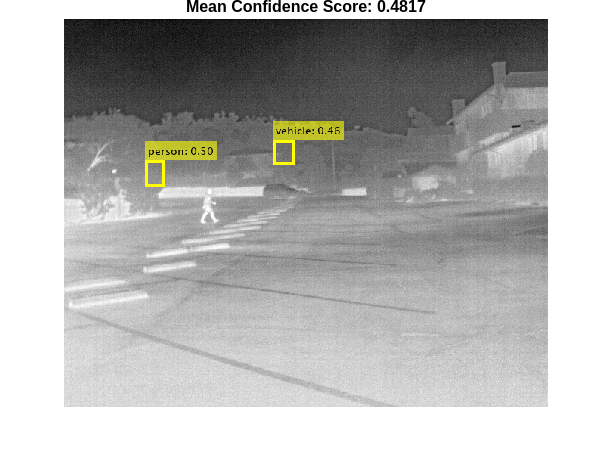

% Load and decode
fid = fopen('./Output/improved_squeezenet/sample_detections_improved.json', 'r');
str = char(fread(fid, inf)');
fclose(fid);
detResults = jsondecode(str);

% Calculate average scores across all samples
numSamples = numel(detResults);
avgScores = zeros(numSamples, 1);

for k = 1:numSamples
    if ~isempty(detResults(k).scores)
        avgScores(k) = mean(detResults(k).scores);
    else
        avgScores(k) = 0; % Ignore samples with zero detections
    end
end

% Find the index of the highest average score
[maxScore, bestIdx] = max(avgScores);
data = detResults(bestIdx);

% Prepare Image
img = imread(data.imageFile);
if size(img, 3) == 1, img = repmat(img, [1 1 3]); end

% Handle Bounding Boxes and Scores
bboxes = data.bboxes;
scores = data.scores;
labels = data.labels;

figure('Name', 'Best Baseline Detection', 'Position', [200 200 800 600]);

if ~isempty(bboxes)
    % Reshape fix
    if isvector(bboxes) && mod(length(bboxes), 4) == 0
        bboxes = reshape(bboxes, 4, [])'; 
    end
    
    % Formatting for annotation
    if ischar(labels), labels = {labels}; end
    if isscalar(scores), scores = [scores]; end
    
    annotatedLabels = cell(numel(labels), 1);
    for j = 1:numel(labels)
        annotatedLabels{j} = sprintf('%s: %.2f', labels{j}, scores(j));
    end
    
    % Annotate with a distinct color (Yellow for the "Winner")
    img = insertObjectAnnotation(img, 'rectangle', bboxes, ...
        annotatedLabels, 'LineWidth', 4, 'FontSize', 14, 'Color', 'yellow');
end

% Display
imshow(img);
title({sprintf('Figure 10: Sample with Highest Average Confidence (Sample %d)', bestIdx), ...
       sprintf('Mean Confidence Score: %.4f', maxScore)}, 'FontSize', 12);

### 4.4. Model Comparison

Table 7 presents a direct comparison between the baseline and champion model configurations, both using the SqueezeNet backbone, to quantify the cumulative impact of the optimisations introduced in the previous section.

% Load results (Baseline vs Champion)
resBase    = readtable('./Output/baseline/ap_results.csv');
resChamp   = readtable('./Output/improved_squeezenet/ap_results_improved.csv');

% Calculate mean Average Precision (mAP)
mAP_Base   = mean(resBase.AP);
mAP_Champ  = mean(resChamp.AP);

% Prepare data rows
rowNames    = [resBase.Class; {'Mean (mAP)'}];
baseScores  = [resBase.AP; mAP_Base];
champScores = [resChamp.AP; mAP_Champ];

% Calculate Percentage Gain: ((Champion - Baseline) / Baseline) * 100
totalGain   = ((champScores - baseScores) ./ baseScores) * 100;

% Construct the Final Ablation Table
ablationTable = table(rowNames, baseScores, champScores, totalGain, ...
    'VariableNames', {'Category', 'Baseline_SqueezeNet_AP', 'Champion_SqueezeNet_AP', 'Total_Gain_Percentage'});

% Display
fprintf('\nTable 7: Model Performance Comparison (Baseline vs Improved)\n');


Table 7: Model Performance Comparison (Baseline vs Improved)


disp(ablationTable);

       Category       Baseline_SqueezeNet_AP    Champion_SqueezeNet_AP    Total_Gain_Percentage
    ______________    ______________________    ______________________    _____________________

    {'person'    }           0.027998                  0.045207                  61.466        
    {'vehicle'   }           0.083871                   0.11981                  42.854        
    {'Mean (mAP)'}           0.055934                   0.08251                  47.512        



The champion achieves substantial gains across both classes: +61.5% AP for `person` and +42.9% AP for `vehicle`. Overall mAP improves by +47.5%, confirming that each optimization contributed meaningfully to detection performance. 

## 5. Cross-Modality Evaluation

To assess the generalization capabilities of the Champion SqueezeNet model, its performance was evaluated across both thermal and RGB modalities using the full test sets provided in the dataset. This analysis illustrates how a model trained exclusively on thermal imagery performs when exposed to a different visual domain. The thermal test set contained 3,493 valid images, while the RGB test set included 3,749 valid images. 

Detection performance was quantified using the Average Precision for each class and the mean Average Precision across classes. The auxiliary function `aux_compare_with_rgb` loads the trained Champion model, performs detection on both test sets, computes per-class AP and mean AP, and outputs the results in a CSV file for easy comparison.

### 5.1. Comparison and Observations

% CSV file path 
csvFile = './Output/rgb_vs_thermal/comparison.csv';

if ~exist(csvFile, 'file')
    error('CSV file not found: %s. Make sure the comparison CSV exists.', csvFile);
end

% Read CSV
comparisonTable = readtable(csvFile);

% Combined table
combinedTable = table(comparisonTable.Class, ...
                      comparisonTable.RGB_AP, ...
                      comparisonTable.Thermal_AP, ...
                      'VariableNames', {'Class', 'RGB_AP', 'Thermal_AP'});

% Display the table in a neat report style
disp('Table 8: RGB vs Thermal Performance');

Table 8: RGB vs Thermal Performance


disp(combinedTable);

       Class         RGB_AP      Thermal_AP
    ___________    __________    __________

    {'person' }    0.00078882     0.036985 
    {'vehicle'}      0.032799      0.12098 
    {'Mean'   }        0.0168        0.079 



On thermal images, as reported in Table 8, the model achieved an AP of 0.03699 for the person class and 0.12098 for the vehicle class, resulting in a mean AP of 0.0790. These results indicate that the model detects vehicles with moderate reliability, benefiting from their larger size and clearer thermal signatures. Pedestrian detection remains challenging due to the smaller spatial scale, low contrast, and occasional occlusions typical in thermal imagery. When applied to RGB images, performance dropped markedly. AP for persons fell to 0.00079, while AP for vehicles decreased to 0.03280, yielding a mean AP of 0.0168. 

The cross-modality evaluation confirms that the Champion SqueezeNet model performs substantially better on thermal images, as expected given that it was trained on this modality. Performance on RGB images is significantly lower, particularly for pedestrians, demonstrating that the model struggles to generalize beyond the modality it was trained on. The combination of limited training data (only 5% of the dataset used) and a lightweight backbone, imposed by hardware constraints, further restricts the model’s capacity to extract robust features across domains.

These results emphasize that while the model is effective within its trained thermal domain, cross-modality generalization would require larger training datasets, more expressive architectures, or additional fine-tuning on RGB data.

## 6. Conclusions

This project explored the development of a thermal-based object detection system for pedestrians and vehicles using the FLIR ADAS dataset. A baseline YOLOv2 detector was implemented and further optimized with data augmentation, hyperparameter tuning, and backbone selection. However, overall detection performance remained limited.

Several factors contributed to these limitations. Thermal imagery inherently lacks detailed texture and color cues, making it challenging to detect small, distant, or partially occluded objects. The dataset exhibits class imbalance and significant variation in object scale, orientation, and density, which complicated the model’s generalization. Additionally, due to hardware constraints, lightweight models such as SqueezeNet were used, and only a small subset (5%) of the dataset was employed for training. This limited the representational capacity of the network and restricted the diversity of examples available for learning.

While data augmentation and hyperparameter optimization improved training stability, mean Average Precision remained modest, and the model struggled to accurately localize objects under complex thermal scenarios. Future improvements could include fine-tuning deeper backbone networks, utilizing a larger portion of the dataset, experimenting with multi-stage detection strategies, or integrating multi-modal data (combining thermal and RGB imagery) to enhance feature richness and detection robustness.

In summary, this project demonstrates that thermal-based object detection is feasible but challenging under limited computational resources. 